# MOTOR SOUND ANALYSIS

#### SIGNAL READING & TREATMENT

[signal, Fs] = audioread('FMX650.mp3'); % Reads the signal

% Converts into mono if the signal is stereo
if size(signal, 2) > 1
    signal = mean(signal, 2);
end

% Deletes the first 0.19 seconds
Time_to_delete = 0.19; % In seconds
signal = Clean(signal, Fs, Time_to_delete, 0);  % Cuts the siganl

t = (0:length(signal)-1) / Fs; % Time Vector

#### TIME & FREQUENCY DOMAIN ANALYSIS

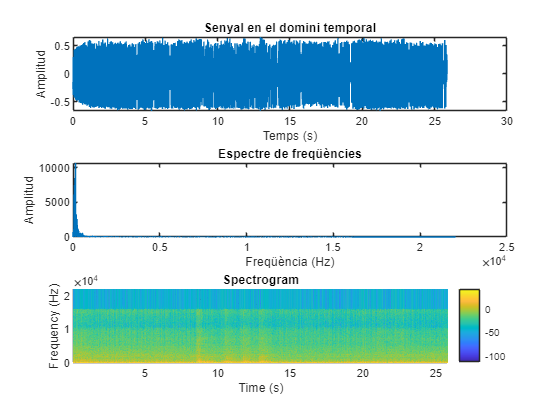

% Time domain plot
figure;
subplot(3,1,1);
plot(t, signal);
xlabel('Temps (s)');
ylabel('Amplitud');
title('Senyal en el domini temporal');

% Frequency domain plot
N = length(signal);
f = linspace(0, Fs/2, floor(N/2)+1);
Y = fft(signal);
magnitude = abs(Y(1:floor(N/2)+1));

subplot(3,1,2);
plot(f, magnitude);
xlabel('Freqüència (Hz)');
ylabel('Amplitud');
title('Espectre de freqüències');

% Spectrogram: Time vs Frequency vs Power
subplot(3,1,3);
window = 1024;
noverlap = window / 2;
nfft = 1024;
[s, f_s, t_s] = spectrogram(signal, window, noverlap, nfft, Fs);
% Convertir a potència en dB
S_dB = 10*log10(abs(s).^2 + eps); % Add eps to avoid log(0)

% 2D Representation
surf(t_s, f_s, S_dB, 'EdgeColor', 'none');
axis tight;
view(0, 90); % 2D View
xlabel('Time (s)');
ylabel('Frequency (Hz)');
zlabel('Power (dB)');
title('Spectrogram');
colorbar;

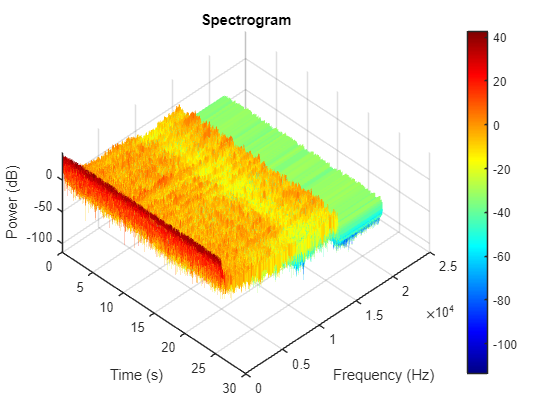

% Plot a 3D Spectrogram: Time vs Frequency vs Power
figure;
surf(t_s, f_s, S_dB, 'EdgeColor', 'none');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
zlabel('Power (dB)');
title('Spectrogram');
view(45, 60);  % 3D View
colormap jet;
colorbar;

## **TELEMETRY**

#### BACKFIRES

% CLEAN SIGNAL FOR A STABLE PERIOD %
signal_freq = Clean(signal, Fs, Time_to_delete, 8.45);
signal_freq = lowpass(signal_freq, 300, Fs);  % Passa-baix a 300 Hz

% Computes the envelope signal
frame = 256;
env = movmean(signal_freq.^2, frame);  % Envelope Signal

% Detects Energy Peaks (Backfires)
min_dist = round(0.05 * Fs);  % Minimun separation between backfires (adjustable)
[~, locs] = findpeaks(env, 'MinPeakHeight', 0.001, 'MinPeakDistance', min_dist);

% Computes the intevervals between backfires
if length(locs) >= 2
    difs = diff(locs) / Fs; % secgonds between peaks
    freq_backfire = 1 ./ difs; % Hz
    mean_freq = mean(freq_backfire);
    fprintf('Mean Backfire Frequency: %.2f Hz\n', mean_freq);
else
    warning('No clear backfires have been detected.');
end

Mean Backfire Frequency: 11.84 Hz


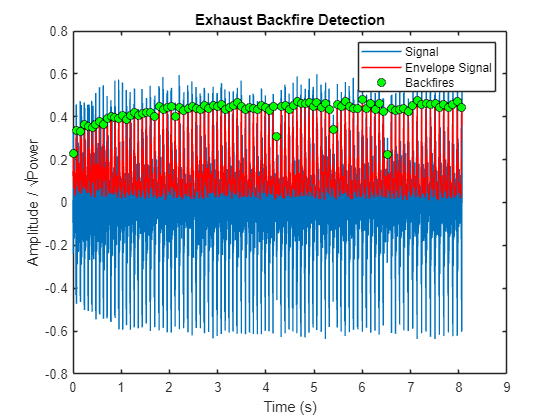


% Signal and peaks' plot
t_backfires_plot = (0:length(signal_freq)-1) / Fs;
figure;
plot(t_backfires_plot, signal_freq); hold on;
plot(t_backfires_plot, sqrt(env), 'r');  % Energy Envelope Signal
plot(locs / Fs, sqrt(env(locs)), 'ko', 'MarkerFaceColor', 'g');  % pics
xlabel('Time (s)');
ylabel('Amplitude / √Power');
title('Exhaust Backfire Detection');
legend('Signal', 'Envelope Signal', 'Backfires');

#### Data extraction

% Extract data
signal_filt = lowpass(signal, 300, Fs);
env = movmean(signal_filt.^2, frame);

% Detects Energy Peaks (Backfires) 
[~, locs] = findpeaks(env, 'MinPeakHeight', 0.001, 'MinPeakDistance', min_dist);
explosions_time = locs / Fs;

% RPM per moving window
window_duration = 1.0; % seconds
window_step = 0.2; % seconds
t_start = 0:window_step:(t(end) - window_duration);
n = length(t_start);
rpm_vector = zeros(1, n);
db_vector = zeros(1, n);
time_vector = t_start + window_duration / 2;

for i = 1:n
    t0 = t_start(i);
    t1 = t0 + window_duration;

    idx_start = max(1, floor(t0 * Fs) + 1);
    idx_end = min(length(signal_filt), floor(t1 * Fs));
    if idx_end <= idx_start
        continue;
    end
    idx = idx_start:idx_end;

    segment = signal_filt(idx);
    if isempty(segment)
        continue;
    end

    pot = mean(segment.^2);
    db_vector(i) = 10 * log10(pot + eps);

    n_expl = sum(explosions_time >= t0 & explosions_time < t1);
    freq_expl = n_expl / window_duration;
    rpm_vector(i) = freq_expl * 60 * 2;  % 4T monocilindric
end


#### RPM

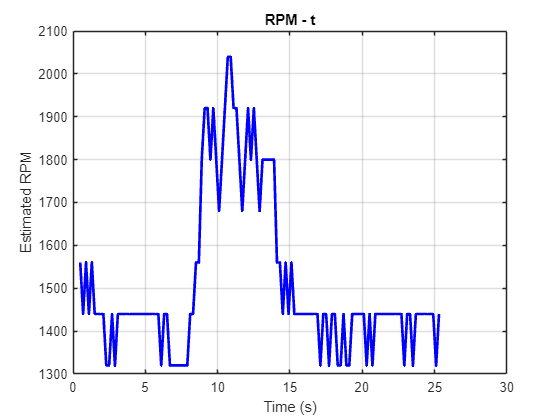

% Plot
figure;
plot(time_vector, rpm_vector, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Estimated RPM');
title('RPM - t');
grid on;

#### TIME vs RPM vs POWER

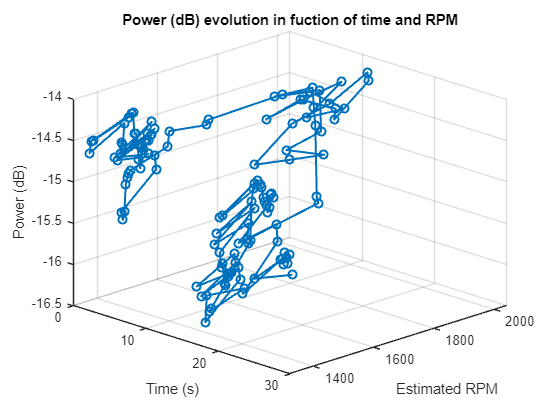

% Define an uniform mesh
temps_grid = linspace(min(time_vector), max(time_vector), 100);
rpm_grid   = linspace(min(rpm_vector),   max(rpm_vector),   100);
[TG, RG] = meshgrid(temps_grid, rpm_grid);

% interpolate values
Z_interp = griddata(time_vector, rpm_vector, db_vector, TG, RG, 'natural');

% Line plot
figure;
plot3(time_vector, rpm_vector, db_vector, '-o', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Estimated RPM');
zlabel('Power (dB)');
title('Power (dB) evolution in fuction of time and RPM');
grid on;
view(45, 25);

### Power of each RPM value

Real power points on each RPM value

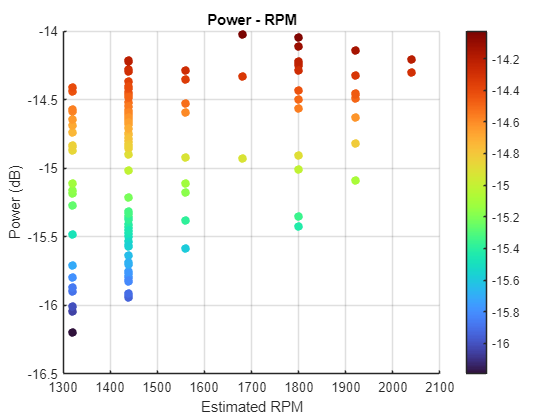

figure;
scatter(rpm_vector, db_vector, 40, db_vector, 'filled');
xlabel('Estimated RPM');
ylabel('Power (dB)');
title('Power - RPM');
grid on;
colormap turbo;
colorbar;

More understandable Power - RPM Plot

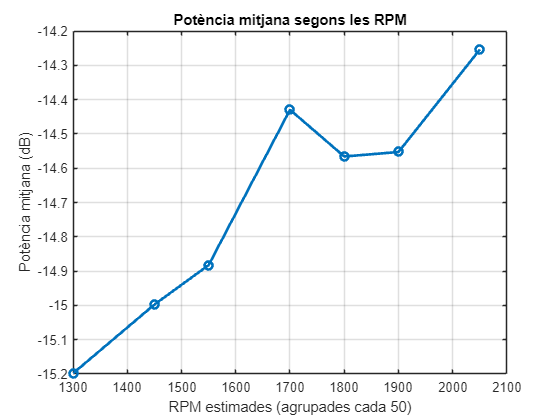

% Round up the RPM per gruops of 50
rpm_rounded = round(rpm_vector / 50) * 50;

% Gruop by RPM and compute the dB mean
[rpm_uniques, ~, idx_grp] = unique(rpm_rounded);
db_means = accumarray(idx_grp, db_vector, [], @mean);

% Resulting plot
figure;
plot(rpm_uniques, db_means, '-o', 'LineWidth', 2);
xlabel('RPM estimades (agrupades cada 50)');
ylabel('Potència mitjana (dB)');
title('Potència mitjana segons les RPM');
grid on;